Clear all the workspace.

close('all');
clear('all');

channelIdxs = 1:64;

tl = tiledlayout(8, 8);

for channelIdx = channelIdxs
    disp(channelIdx)
    generateTemplates(tankObj, 'K15&&K14', 4, channelIdx, 20e-3, 20, false, tl);
end

actionToExecute = 2;
 

if actionToExecute == 1
    path = 'P:\Rat\R03\Therapy\RO3Recordings\K15&&K14\stim6-base-191214-174256\RawData\Raw_P1_Ch_001.mat';

    generateBaselineSignal(path, 150, 25000, [0.5, 99.5], true);
end

Generate all the templates from the specified Animal, Block and channel.

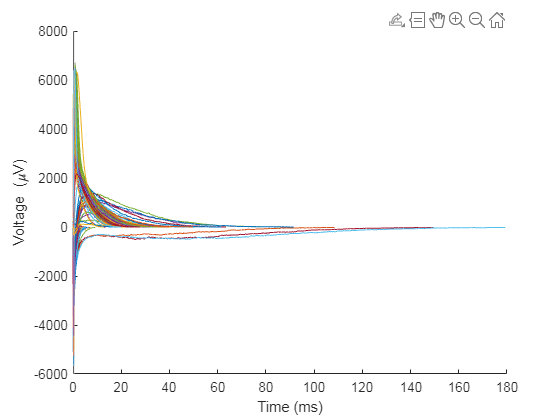

if actionToExecute == 2

    %%%%%%%%%%%%%% nigeLab integration %%%%%%%%%%%%%%%%
    tankPath = 'P:\Rat\R03\Therapy\RO3Recordings_Tank.mat';
    load(fullfile(tankPath));

    animalObj = getChildObj(tankObj, 'K15&&K14');
    blockObj = getChildObj(animalObj, 4);
    data = blockObj{'raw', 34, :};
    data = data{1};

    [stim, blankingNSamples] = getStim(blockObj);
    blankingNSamples = blankingNSamples + 5; % Arbitrary increase in the computed blanking window
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % %%%%%%%%%%%%%%%%% Data from path %%%%%%%%%%%%%%%%%%
    % dataPath = 'P:\Rat\ComplexBoxHealthyPilotStudy\StimTriggeredConnectivity\410\410_2023_01_26_35\410_2023_01_26_35_RawData\410_2023_01_26_35_Raw_P1_Ch_015.mat';
    % stimPath = 'P:\Rat\ComplexBoxHealthyPilotStudy\StimTriggeredConnectivity\410\410_2023_01_26_35\410_2023_01_26_35_StimTimes.mat';
    % 
    % load(fullfile(dataPath), 'data');
    % load(fullfile(stimPath));
    % 
    % stim = StimOnsets;
    % blankingNSamples = StimOffsets - StimOnsets;
    % %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    generateTemplates(data, stim, 25000, blankingNSamples, 200, true);
end

if actionToExecute == 3
    generateSnippet(150, 25000, true);
end